# Transfer Learning with Resnet 18

We re-use resnet 18 in an matlab example and mammogram dataset

clc, close all, clear all;

## Load Data

% unzip('MerchData.zip');
% imds = imageDatastore('MerchData','IncludeSubfolders',true,'LabelSource','foldernames');
imds = imageDatastore("data_roi_single/",'IncludeSubfolders',true,'LabelSource','foldernames');
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.8,'randomized');

## Display Random Images from dataset

This code displays images from **training dataset **

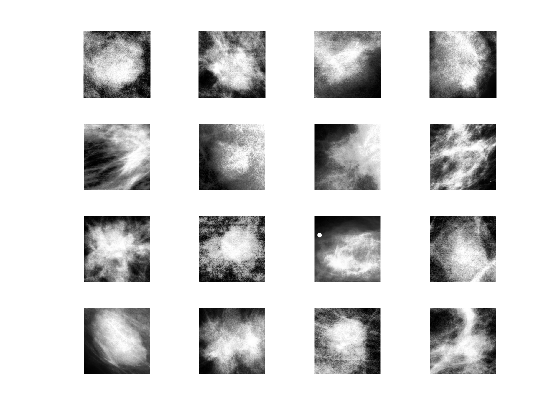

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## Load Pretrained Network

net = resnet50;
% analyzeNetwork(net);

## Replace Final Layers

To learn faster in the new layers than in the transferred layers, increase the learning rate factors of the fully connected layer

numClasses = numel(categories(imdsTrain.Labels));
lgraph = layerGraph(net);

newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newFCLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);

## Train Network

The network requires input images of size 224-by-224-by-3, but the images in the image datastore have different sizes. **Use an augmented image datastore to automatically resize the training images. **You can also use an `imageDataAugmenter`** to specify additional augmentation operations to perform on the training image**s to help prevent the network from overfitting.

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

### Training options:

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',5, ...
    'Verbose',true, ...
    'Plots','training-progress');

Execute Training:

trainedNet = trainNetwork(augimdsTrain,lgraph,options);

Error using trainNetwork (line 165)
The training images are of size 224x224x1 but the input layer expects images of size 224x224x3.

## Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

YPred = classify(trainedNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)